# Project 1 - The Toomre Model

In this project, we implement the Toomre model of galactic interaction in 3D for a generalized number of galaxies. The Toomre model simplifies the description of a galaxy to a core with a population of massless stars in circular orbits around it. Provided initial positions and velocities of the cores and stars, we evolve the system via a second-order iteration in time, up to a final time.

Once implemented, we study the simulation for four cases: a binary star system, single core, glancing interaction between two galaxies, and a three-body system. For each case, we will also complete a 4-level convergence test.

## Theory and Implementation Overview

### Iteration Relations

First, we define a discrete time grid $t^n$ with $1\leq n\leq n_t$ for $n_t=2^l+1$ iteration steps, defined in terms of level parameter $l$.

At the $n^{th}$ iteration step, the system is described by the position of cores and stars in 3D space, $R^n_i=(X^n_i, Y^n_i, Z^n_i)$ and $r^n_j=(x^n_j, y^n_j, z^n_j)$ respectively. Here,$1\leq i\leq n_c$ and $1\leq j\leq n_s$ where $n_c$ and $n_s$ are the number of cores and stars respectively. In an iteration step, we use the centered second-order scheme to determine a state based on the previous two.


$$\frac{R_i^{n+1} - 2 R_i^{n} + R_i^{n-1}}{\Delta t^2}=A_i^{n+1}\;\;,\;\;\frac{r_j^{n+1} - 2 r_j^{n} + r_j^{n-1}}{\Delta t^2}=a_j^{n+1}$$


Where $\Delta t=t_{max} / 2^l$ is the time step with $A_i$ and $a_j$ the acceleration of cores and stars. Solving for $R_i^{n+1}$ and $r_j^{n+1}$ gives the iteration relations. This is implemented as the `iterate` function.


$$R_i^{n+1}=2R_i^n-R_i^{n-1}+\Delta t^2 \cdot A_i^{n+1}\;\;,\;\; r_j^{n+1}=2r_j^n-r_j^{n-1}+\Delta t^2 \cdot a_j^{n+1}$$


With core masses $M_i$ and massless stars, accelerations are given as follows. Note that in dimensionless units, the gravitational constant is $G=1$. Core and star accelerations are implemented in `accelCores` and `accelStars` functions respectively.


$$A_i =\sum_{k\not= i} \frac{M_k }{|R_{k,i} |^3 }\cdot R_{k,i} \;\;\;\;,\;\;R_{k,i} =R_k -R_i$$



$$a_j =\sum_i \frac{M_i }{\left|r_{i,j} {\left|\right.}^3 \right.}\cdot r_{i,j} \;\;\;\;,\;\;r_{i,j} =R_i -r_j$$


### Initial Conditions

The first state of our system is determined by initial positions $R_{0_i}$ and $r_{0_j}$. In addition, the second state requires initialization provided initial velocities $V_{0_i}$ and $v_{0_j}$ of cores and stars.


$$R_i^1 =R_{0_i } \;\;\;\;,\;\;r_j^1 =r_{0_j }$$



$$R_i^2 =R_{0_i } +\Delta t\cdot V_{0_i } +\frac{\Delta t^2 }{2}\cdot A_i^1 \;\;\;\;,\;\;\;r_j^2 =r_{0_j } +\Delta t\cdot v_{0_j } +\frac{\Delta t^2 }{2}\cdot a_j^1$$


The initial conditions for cores are provided by the user. For the stars however, provided $n_{s_i}$ the number of stars for each core, we assign uniformly random positions and velocities (ranges are provided by the user) constrained to a circular orbit. Four parameters are chosen at random for each star as shown below: $r, \theta, \phi, \alpha$. To avoid repetition in code, we implemented the `randsInRange` function to randomly generate these four parameters in desired ranges.

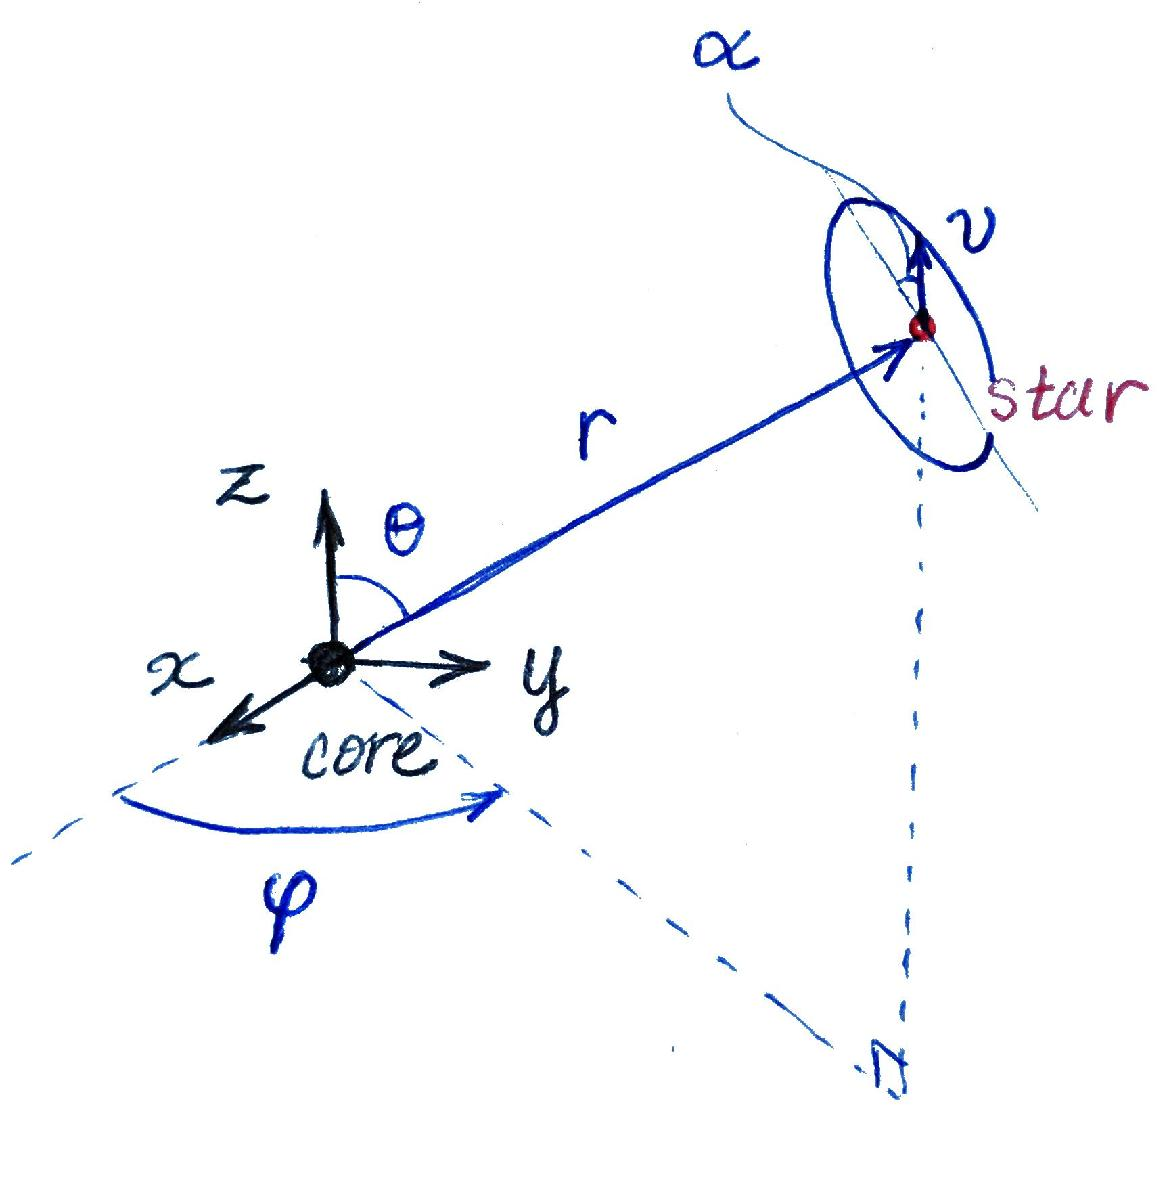

The first three $r,\theta,\phi$ determine the initial position of a star relative to its core in spherical coordinates. And the last one $\alpha$ defines the direction of its initial velocity. Note that since the orbit is constrained to be circular, the star velocity is constrained to a circle (shown in the above figure) and only one degree of freedom remains. Equating the centrifugal force and the gravitational force on the star, gives $v$ the magnitude of the star velocity.


$$\frac{v^2 }{r}=\frac{M_i }{r^2 }\;\;\;\Rightarrow \;\;v=\sqrt{\;\frac{M_i }{r}}$$


Finally, position and velocity of the star relative to its core is then determined as below. To find the absolute position and velocities, we simply add the respective core position and velocity to the following.


$$r_j=(r \sin(\theta)\cos(\phi), \; r \sin(\theta)\sin(\phi),\; r \cos(\theta))$$



$$v_j =\sqrt{\;\frac{M_i }{r}}\;\hat{v} \;\;\;\;,\;\;\;\;\hat{v} =\left(-\mathrm{sin}\left(\alpha \right)\mathrm{sin}\left(\phi \right)-\mathrm{cos}\left(\alpha \right)\mathrm{cos}\left(\theta \right)\mathrm{cos}\left(\phi \right),\;\mathrm{sin}\left(\alpha \right)\mathrm{cos}\left(\phi \right)-\mathrm{cos}\left(\alpha \right)\mathrm{cos}\left(\theta \right)\mathrm{sin}\left(\phi \right),\;\mathrm{cos}\left(\alpha \right)\mathrm{sin}\left(\theta \right)\right)$$


### Convergence Testing

To test the validity of our simulation, we perform a 4-level convergence test on the $x$ position of a star (if no stars are simulated, a core is used instead). For this, the $x$ position is tracked over complete simulations at four adjacent levels $l-3$ through $l
$. And the scaled differences between adjacent levels are plotted and compared.


$$\Delta x_{l-3, l-2} = x_{l-3} - x_{l-2}$$



$$4 \cdot \Delta x_{l-2, l-1} = 4 \cdot (x_{l-2} - x_{l-1})$$



$$16 \cdot \Delta x_{l-1, l} = 16 \cdot (x_{l-1} - x_{l})$$


Since the error in calculated values using a second-order scheme scales with $\Delta t^2$ (and $\Delta t$ varies by a factor of two across adjacent levels), we expect these trends to be close to each other for a converging solution.

Tracking of the $x$ position for a given level is implemented in the `trackX` function.

## Simulated Examples

While our implementation is generalized to 3D, we have restricted the following results to 2 dimensions of $x, y$. This means fixing the following configuration parameters (the asterisks indicate an arbitrary value). If the parameters below are unclear, please look at the `testToomre.m` script where I have commented the exact definitions.

rc0 = [*, *, 0; *, *, 0];
vc0 = [*, *, 0; *, *, 0];
range_thetas = [pi/2, pi/2; pi/2, pi/2];
range_phis = [0, 2 * pi; 0, 2 * pi];
range_alphas = [pi/2, pi/2; pi/2, pi/2];

Furthermore, the GUI options are kept more or less the same in these examples.

do_save = true;
trace_cores = true;
delay = 0;
padding = 2;
save_name = 'toomre.avi';

color_cores = [[9, 18, 110] / 255; [173, 3, 3] / 255];
color_stars = ['b'; 'r'];
size_cores = 10 * mc .^ (1 / 3);
size_stars = 3;

### Binary System

First, to test our implementation, we simulate the simple binary system consisting of two cores in mutual circular orbit about their common center of mass. The initial condition is shown below.

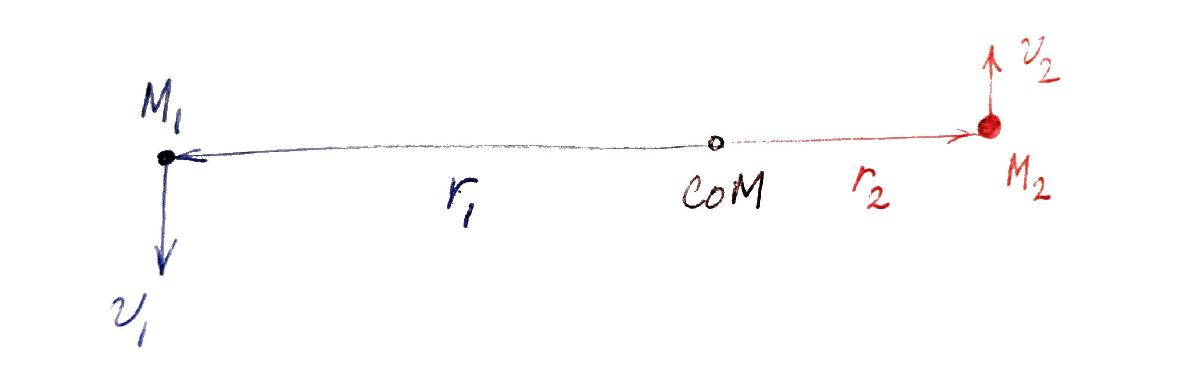

Choosing the correct initial conditions is critical here. For ease, we choose center of mass to be at the origin. Since the problem is scale-invariant, we further require the distance between cores to be $\Delta r=1$. Therefore imposing the following conditions on the magnitudes of $r_i$.


$$M_1 r_1 =M_2 r_2 \;\;\;\;,\;\;r_1 +r_2 =1\;\;\;\Rightarrow \;\;r_{1/2} =\frac{M_{2/1} }{M_1 +M_2 }$$


And the radial equations of motion give $v_i$ the velocity magnitudes.


$$\frac{v_1^2 }{r_1 }=M_2 \;\;\;\;,\;\frac{v_2^2 }{r_2 }=M_1 \;\;\;\Rightarrow \;v_{1/2} =\sqrt{M_{2/1} \;r_{1/2} }$$


We choose $M_1=1$ and $M_2=4$ and simulate this system with the following configuration. See **binary.avi** for the video.

mc = [1; 4];
ns = [0; 0];
rc0 = [-4/5, 0, 0; 1/5, 0, 0];
vc0 = [0, -4/sqrt(5), 0; 0, 1/sqrt(5), 0];

tmax = 3;
level = 9;

The result is as expected; the cores circularly orbit each other about the origin. On the left is a snapshot of the simulation with core positions traced. And on the right is the 4-level convergence test results on the $x$ position of the first core (in blue).

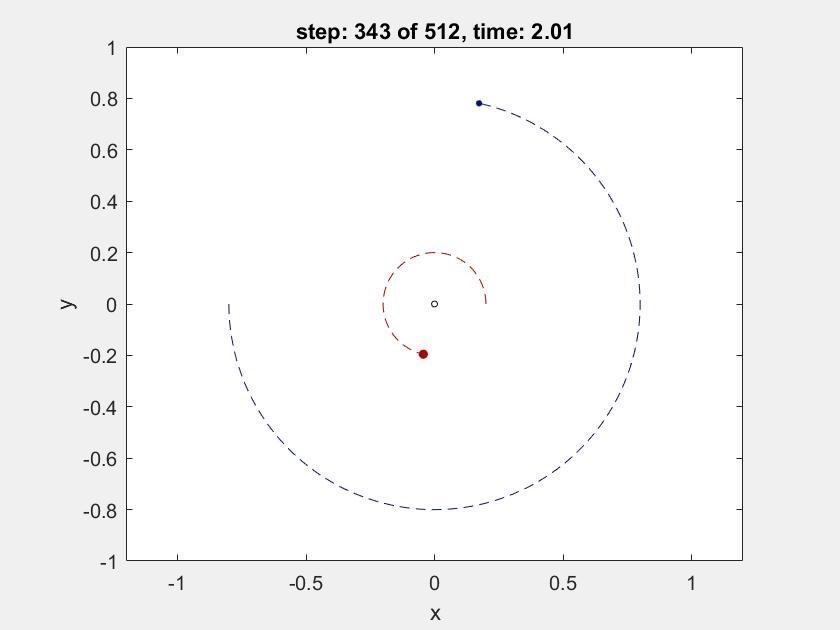  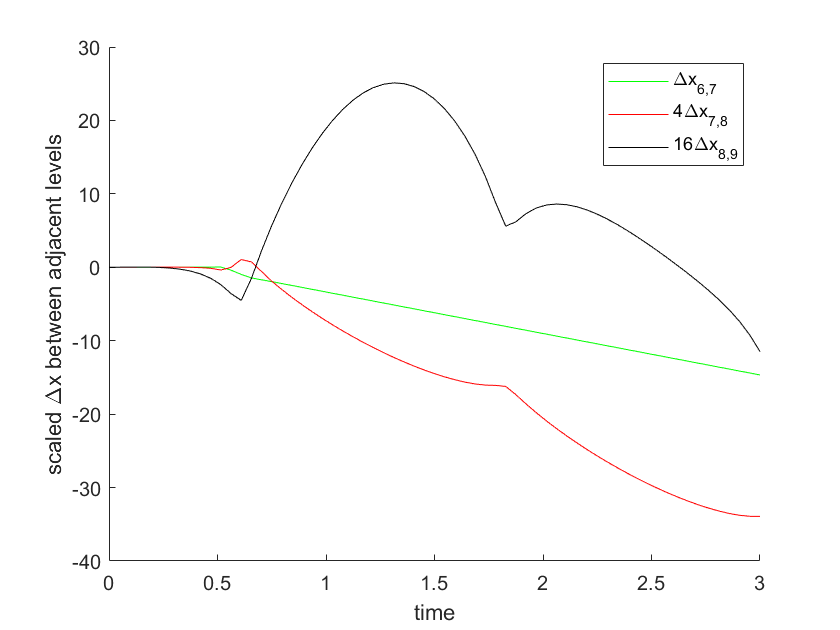

**The convergence plot is certainly incorrect and not indicative of the quality of convergence. I have included it here solely to show my work!** The plot shows a difference of $\Delta x_{6,7} \approx12$ toward the end of simulation, meaning that in either the $l=6$ or $l=7$ simulation the blue core must have diverged significantly from its circular orbit. I have checked both levels and that is not the case.

There is certainly a problem with the convergence testing code. I have spent hours and to my surprise not found the issue. I might have been looking in the wrong places or perhaps missed a nuance with MATLAB. It would be great if you could find what I did wrong.

### Single Core

To further test our implementation for star dynamics, we simulate a single core moving with constant velocity with a few stars orbiting it. The initial conditions for this example are simple and require no derivation. I chose a low star count so it would be easy to discern their individual orbits.

The configuration parameters are below. See **single.avi** for the video.

mc = [1];
ns = [10];
rc0 = [0.5, 0, 0];
vc0 = [-1, 0, 0];
range_rs = [0.02, 0.4];

tmax = 1;
level = 9;

As observed in the video, the stars maintain their circular orbits throughout the simulation, confirming the correctness of our star dynamics. Here again is the incorrect convergence results. Same comments made for the previous example applies here.

### 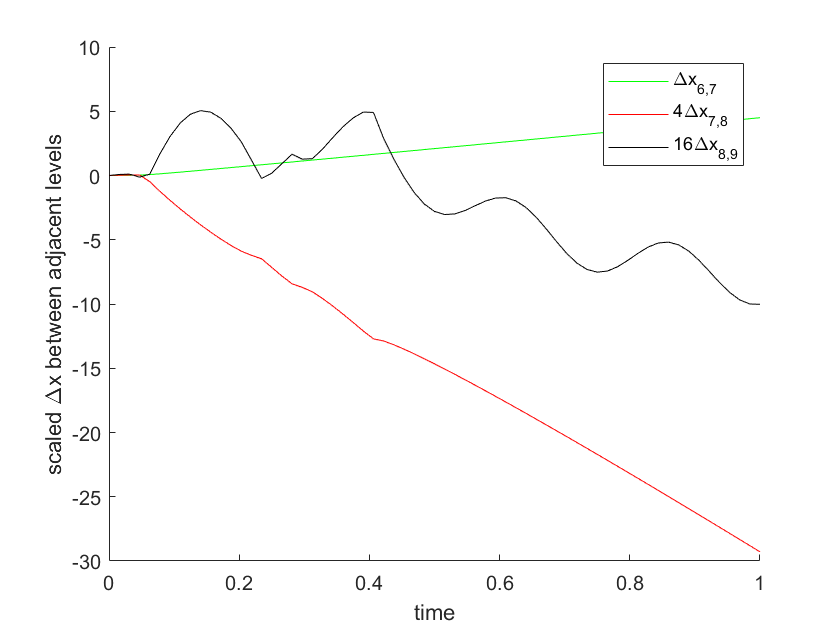

### Spiral Galaxies

The idea is to study a glancing interaction between two galaxies. The simulation is more error-prone in cases involving close interaction, and hence more likely to diverge.

Finding the right initial conditions for the cores took some time and involved trial and error. I did however notice a relation between the mass, time, and length scales that helped determine the ideal conditions. By setting $G=1$, we are constraining the dimensions in our problem as $[G]=L^3/MT^2=1$. This means that the quantity $c\equiv G \cdot mt^2/l^3=mt^2/l^3$ (where $m,t,l$ are the mass, time, and length scales) is a dimensionless constant that determines the type of our problem. I found that for a $c\approx 10$, the interaction is most interesting.

The configuration parameters I ultimately used are below. The difference between core parameters below is mostly to produce an interesting result. See **spiral.avi** for the video.

mc = [1; 4];
ns = [2000; 2000];
rc0 = [-0.5, 1, 0; 1, -1, 0];
vc0 = [0, -2, 0; 0, 2, 0];
range_rs = [0.1, 0.6; 0.2, 0.7];

tmax = 2;
level = 9;

To the left is a snapshot of the simulation showing core tracings. We see that the blue core of lower mass has been deflected from its initial track more than the red core, which is to expected due to its lower inertia. We also see the stars develop a beautiful spiral pattern, reminiscent of our own galaxy.

To the right is the incorrect convergence results. Same comments made for the previous examples applies here.

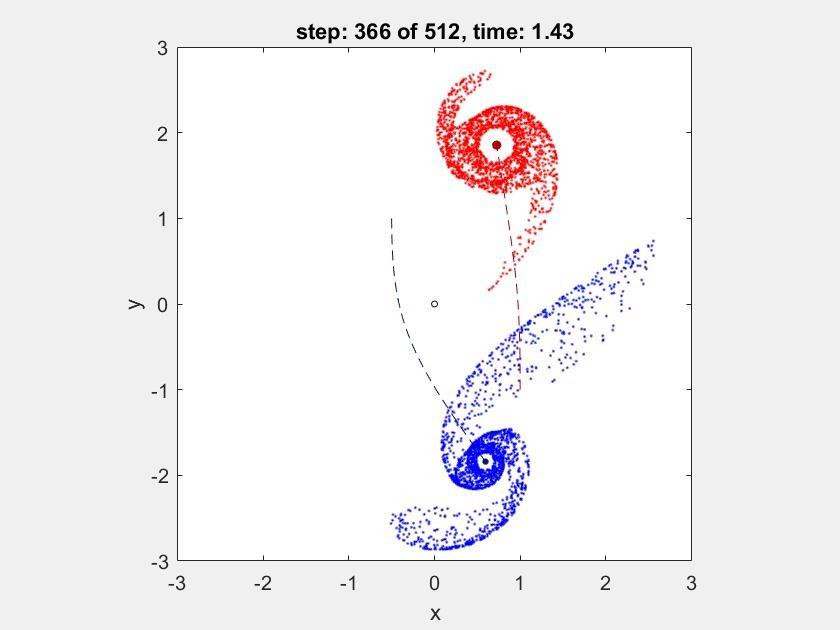  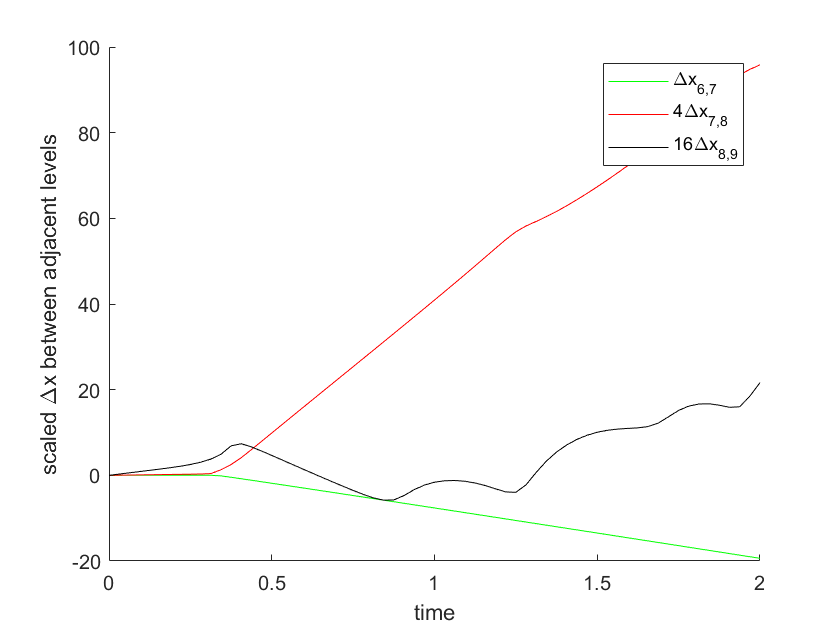

### Three Body System

This example is mostly for fun and to demonstrate the flexibility of my simulation. Simulating three cores (or more) is possible since we have not constrained the number of cores in the implementation.

The configuration parameters for this example follow. See **three-body.avi** for the video.

mc = [1; 2; 2];
ns = [0; 0; 0];
rc0 = [0, -1, 0; 1, 1, 0; -0.5, 1, 0];
vc0 = [1, 0.5, 0; -1, 0, 0; 0, -1, 0];

tmax = 4;
level = 9;

A snapshot of the simulation is below showing a trace of the cores. I do not have much else to comment on.

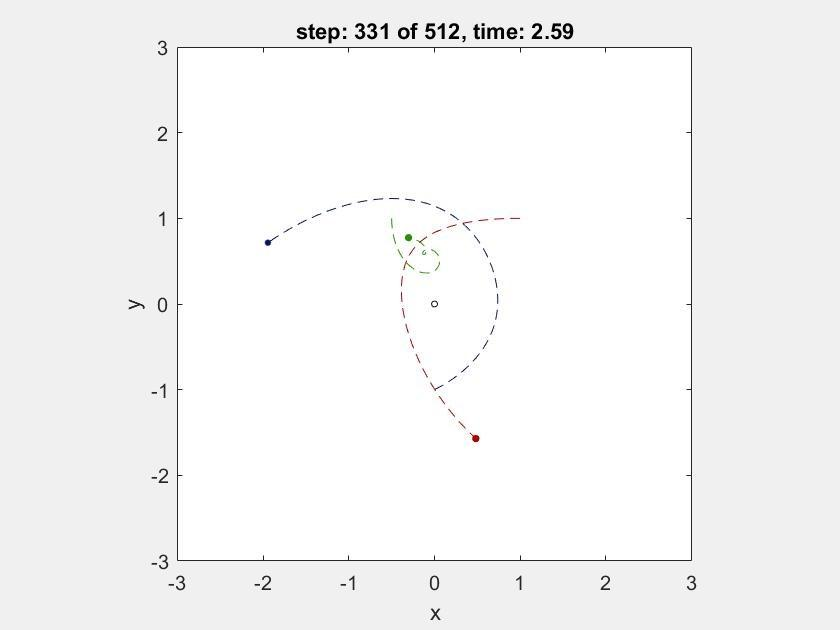

#### Thank you for the time you spent reading my report.